Image = imread('HotCrossBuns.jpg');
[x, y] = createMask2(Image);
W = x((160:230), (162:200));
Map = zeros(71,500);
Map(1:71, 1:39) = W;
Map(20:21, :) = 1;
Map(28:29, :) = 1;
Map(36:37, :) = 1;
Map(44:45, :) = 1;
Map(52:53, :) = 1;
BackGroundNote = Map(:, 40:51);

Ball = readmatrix('ball.csv');
Ball = logical(Ball(1:8,1:12));


imshow(BackGroundNote)

E1_4  = LineNoteMap1_4(21, BackGroundNote);
C1_4  = LineNoteMap1_4(29, BackGroundNote);
A1_4  = LineNoteMap1_4(37, BackGroundNote);
F1_4  = LineNoteMap1_4(45, BackGroundNote);
FL1_4 = LineNoteMap1_4(17, BackGroundNote);
DL1_4 = LineNoteMap1_4(25, BackGroundNote);
BL1_4 = LineNoteMap1_4(33, BackGroundNote);
GL1_4 = LineNoteMap1_4(41, BackGroundNote);
EL1_4 = LineNoteMap1_4(49, BackGroundNote);

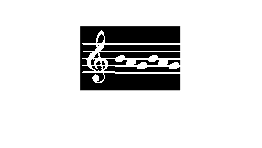

Line = [W BL1_4 A1_4 GL1_4 BL1_4 A1_4 GL1_4];
imshow(Line)

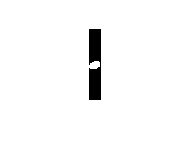

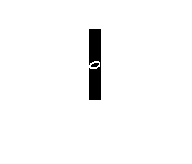

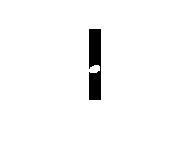

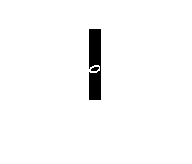

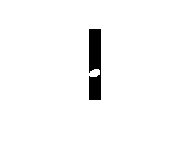

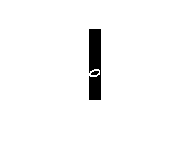

Notes = ' BL1_4 BL1_2 A1_4 A1_2 GL1_4 GL1_2 BL1_4 BL1_2 A1_4 A1_2 GL1_4 GL1_2'

Notes = Getter(Line)

Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   0   0   0   0   0   1   0;
   0   1   1   0   0   0   0   0   0   0   1   0;
   1   1   0   0   0   0   0   0   0   1   1   0;
   1   1   0   0   0   0   0   0   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
imshow(Ball)

function [Caught] = Getter(im)
	E1_4.map = NoteMap1_4(21);
	E1_4.name = 'E1_4';       
	C1_4.map = NoteMap1_4(29);
	C1_4.name = 'C1_4';       
	A1_4.map = NoteMap1_4(37);
	A1_4.name = 'A1_4';       
	F1_4.map = NoteMap1_4(45);
	F1_4.name = 'F1_4';
	FL1_4.map = NoteMap1_4(17);
	FL1_4.name = 'FL1_4';
	DL1_4.map = NoteMap1_4(25);
	DL1_4.name = 'DL1_4';
	BL1_4.map = NoteMap1_4(33);
	BL1_4.name = 'BL1_4';
	GL1_4.map = NoteMap1_4(41);
	GL1_4.name = 'GL1_4';
	EL1_4.map = NoteMap1_4(49);
	EL1_4.name = 'EL1_4';

    E1_2.map = NoteMap1_2(21);
	E1_2.name = 'E1_2';       
	C1_2.map = NoteMap1_2(29);
	C1_2.name = 'C1_2';       
	A1_2.map = NoteMap1_2(37);
	A1_2.name = 'A1_2';       
	F1_2.map = NoteMap1_2(45);
	F1_2.name = 'F1_2';
	FL1_2.map = NoteMap1_2(17);
	FL1_2.name = 'FL1_2';
	DL1_2.map = NoteMap1_2(25);
	DL1_2.name = 'DL1_2';
	BL1_2.map = NoteMap1_2(33);
	BL1_2.name = 'BL1_2';
	GL1_2.map = NoteMap1_2(41);
	GL1_2.name = 'GL1_2';
	EL1_2.map = NoteMap1_2(49);
	EL1_2.name = 'EL1_2';

	Masks = [E1_4 C1_4 A1_4 F1_4 FL1_4 DL1_4 BL1_4 GL1_4 EL1_4 E1_2 C1_2 A1_2 F1_2 FL1_2 DL1_2 BL1_2 GL1_2 EL1_2];
	
	Caught = [];
	Sz = size(im);
	snd = Sz(2);
    for q = 1 : snd - 11
		for Test = Masks
			if ((im(:, q:q + 11) & Test.map) == Test.map) & (~(im(:, q:q + 11) & Test.map) == ~Test.map)
				Caught = [Caught ' ' Test.name];
                %im(:, q:q + 11)
                figure
                imshow(Test.map)
                %return
			end
        end
	end
end


function [S] = LineNoteMap1_4(NoteBase, BackGroundNote)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
S = S | BackGroundNote;
S(NoteBase:NoteBase + 7,:) = S(NoteBase:NoteBase + 7,:) | Ball;
end

function [S] = LineNoteMap1_2(NoteBase, BackGroundNote)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
S = S | BackGroundNote;
S(NoteBase:NoteBase + 7,:) = S(NoteBase:NoteBase + 7,:) | Ball;
end

function [S] = NoteMap1_4(NoteBase)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
z = NoteBase;
x = NoteBase + 7;
S(z:x,:) = S(z:x,:) | Ball;
end

function [S] = NoteMap1_2(NoteBase)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   0   0   0   0   0   1   0;
   0   1   1   0   0   0   0   0   0   0   1   0;
   1   1   0   0   0   0   0   0   0   1   1   0;
   1   1   0   0   0   0   0   0   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
z = NoteBase;
x = NoteBase + 7;
S(z:x,:) = S(z:x,:) | Ball;
end

function [BW,maskedRGBImage] = createMask2(RGB)
% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 0.009;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.810;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
